# Passive Low-Pass Filters – Theory, Circuit Analysis, and Response Characteristics

**MATLAB Tutorial for Undergraduate Engineering Students**

Based on: Chapter 15 - Active Filters (Floyd's Electronic Devices)

Author: Kessad Mohamed Dhia Eddine

Github: DhiaKessad

Objective: This comprehensive tutorial covers passive low-pass filter theory, including RC, RL, and RLC configurations, frequency response characteristics (Butterworth, Chebyshev, Bessel), time-domain behavior, and MATLAB modeling.

## 1. Introduction to Filter Theory

**What is a Filter?**

A filter is a circuit that passes certain frequencies and attenuates or rejects all other frequencies. This property is called selectivity. Filters are fundamental building blocks in signal processing, communication systems, and electronic instrumentation.

**Key Filter Terminology:**

- **Passband:** The range of frequencies that are allowed to pass through with minimum attenuation (usually defined as less than -3 dB)

- **Critical Frequency (fc):** Also called cutoff frequency, defines the end of the passband where response drops to -3 dB (70.7% or 0.707) from passband

- **Transition Region:** The region between passband and stopband where the gain transitions from pass to stop

- **Stopband:** The region where frequencies are significantly attenuated

- **Roll-off Rate:** The rate at which gain decreases in the transition region, measured in dB/decade or dB/octave

- **Pole:** For filters, a pole represents an RC circuit that affects frequency response. More poles result in steeper roll-off rates

## 2. Low-Pass Filter Fundamentals

**Definition and Characteristics**

A low-pass filter (LPF) passes frequencies from DC to the critical frequency (fc) and significantly attenuates all other frequencies above fc.

**Bandwidth Definition:**

For a low-pass filter, the bandwidth is equal to the critical frequency:


$$BW = f_c$$


**Ideal vs. Actual Response:**

- **Ideal Response:** "Brick-wall" characteristic with instantaneous transition at fc - not achievable in practice

- **Actual Response:** Gradual roll-off beginning at fc, with rate determined by filter order (number of poles)

**Roll-off Rates by Filter Order:**

- First-order (1-pole): -20 dB/decade

- Second-order (2-pole): -40 dB/decade

- Third-order (3-pole): -60 dB/decade

- nth-order (n-pole): -20n dB/decade

Note: -20 dB/decade = -6 dB/octave

## 3. RC Low-Pass Filter (Single-Pole)

**Circuit Configuration**

The simplest passive low-pass filter consists of:

- A resistor (R) in series with the input

- A capacitor (C) connected from output to ground

- Output voltage measured across the capacitor

Circuit Topology:

**Mathematical Derivation**

Using voltage divider with impedances in s-domain:

Impedances:


$$Z_R = R$$



$$Z_C = \frac{1}{sC}$$


Transfer function using voltage divider:


$$H(s) = \frac{Z_C}{Z_R + Z_C} = \frac{\frac{1}{sC}}{R + \frac{1}{sC}}$$


Multiplying numerator and denominator by sC:


$$H(s) = \frac{1}{1 + sRC}$$


**Critical Frequency Derivation**

The critical frequency occurs when the capacitive reactance equals resistance:


$$X_C = R$$



$$\frac{1}{2\pi f_c C} = R$$


Solving for fc:


$$f_c = \frac{1}{2\pi RC}$$


At the critical frequency, the output voltage is 70.7% of input (or -3 dB).

## 4. MATLAB Implementation - RC Low-Pass Filter

Define component values for an audio application

% RC Low-Pass Filter Parameters
R_rc = 1e3;              % Resistance = 1 kΩ
C_rc = 1000e-9;           % Capacitance = 100 nF

% Calculate critical frequency
fc_rc = 1 / (2 * pi * R_rc * C_rc);
wc_rc = 2 * pi * fc_rc;
tau_rc = R_rc * C_rc;

% Display parameters
fprintf('RC LOW-PASS FILTER PARAMETERS:\n');

RC LOW-PASS FILTER PARAMETERS:


fprintf('================================\n');

fprintf('Resistance R = %.2f kΩ\n', R_rc/1e3);

Resistance R = 1.00 kΩ


fprintf('Capacitance C = %.2f nF\n', C_rc*1e9);

Capacitance C = 1000.00 nF


fprintf('Critical frequency fc = %.2f Hz\n', fc_rc);

Critical frequency fc = 159.15 Hz


fprintf('Time constant τ = %.2f μs\n', tau_rc/1e-6);

Time constant τ = 1000.00 μs


fprintf('Roll-off rate: -20 dB/decade (single-pole)\n\n');

Roll-off rate: -20 dB/decade (single-pole)




% Create transfer function
s = tf('s');
H_rc = 1 / (1 + s*R_rc*C_rc);

fprintf('Transfer Function H(s):\n');

Transfer Function H(s):


disp(H_rc);

  tf with properties:

       Numerator: {[0 1]}
     Denominator: {[1.0000e-03 1]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



## 5. Frequency Response Analysis - RC Filter

Generate frequency vector (logarithmic spacing)

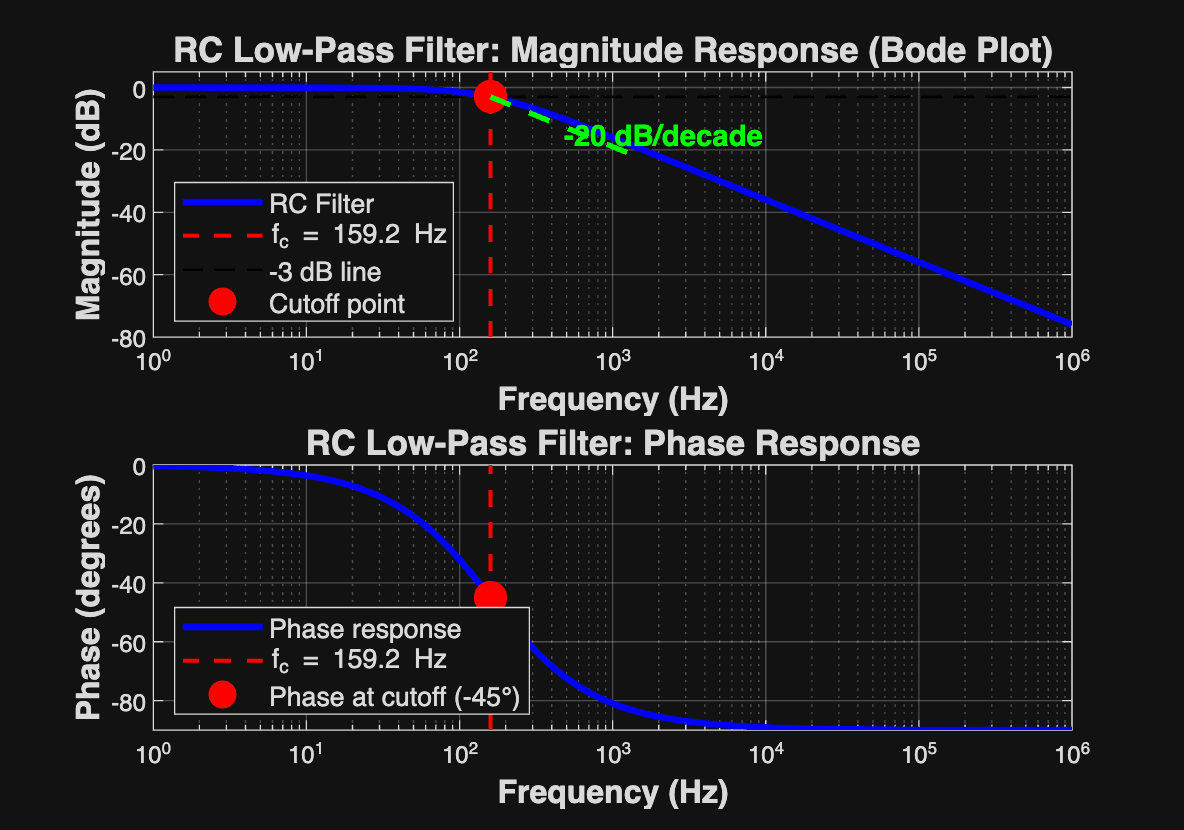

f = logspace(0, 6, 2000);    % 1 Hz to 1 MHz
w = 2 * pi * f;

% Compute frequency response
[mag_rc, phase_rc] = bode(H_rc, w);
mag_rc = squeeze(mag_rc);
phase_rc = squeeze(phase_rc);
mag_dB_rc = 20 * log10(mag_rc);

% Create comprehensive Bode plot
figure('Position', [100, 100, 1000, 700]);

% Magnitude plot
subplot(2, 1, 1);
semilogx(f, mag_dB_rc, 'b-', 'LineWidth', 2.5);
hold on;
semilogx([fc_rc, fc_rc], [-80, 5], 'r--', 'LineWidth', 1.5);
semilogx([f(1), f(end)], [-3, -3], 'k--', 'LineWidth', 1);
plot(fc_rc, -3, 'ro', 'MarkerSize', 12, 'MarkerFaceColor', 'r');

% Add roll-off rate annotation
f_decade = fc_rc * 10;
semilogx([fc_rc, f_decade], [-3, -23], 'g--', 'LineWidth', 2);
text(fc_rc*3, -15, '-20 dB/decade', 'FontSize', 11, 'Color', 'g', 'FontWeight', 'bold');

hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');
title('RC Low-Pass Filter: Magnitude Response (Bode Plot)', 'FontSize', 13, 'FontWeight', 'bold');
legend('RC Filter', sprintf('f_c = %.1f Hz', fc_rc), '-3 dB line', ...
       'Cutoff point', 'Location', 'southwest', 'FontSize', 10);
ylim([-80, 5]);
xlim([f(1), f(end)]);

% Phase plot
subplot(2, 1, 2);
semilogx(f, phase_rc, 'b-', 'LineWidth', 2.5);
hold on;
semilogx([fc_rc, fc_rc], [-90, 0], 'r--', 'LineWidth', 1.5);
plot(fc_rc, -45, 'ro', 'MarkerSize', 12, 'MarkerFaceColor', 'r');
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Phase (degrees)', 'FontSize', 12, 'FontWeight', 'bold');
title('RC Low-Pass Filter: Phase Response', 'FontSize', 13, 'FontWeight', 'bold');
legend('Phase response', sprintf('f_c = %.1f Hz', fc_rc), ...
       'Phase at cutoff (-45°)', 'Location', 'southwest', 'FontSize', 10);
ylim([-90, 0]);
xlim([f(1), f(end)]);

## Analysis of RC Filter Response

**Frequency Domain Observations:**

- **Passband (f**** << fc):** Gain ≈ 0 dB (unity gain), phase ≈ 0°

- **Critical frequency (f = fc):** Gain = -3 dB, phase = -45°

- **Stopband (f >> fc):** Gain decreases at -20 dB/decade, phase → -90°

**At 10×fc:** Gain = -20 dB (10% of input magnitude)

**At 100×fc:** Gain = -40 dB (1% of input magnitude)

The -20 dB/decade roll-off is characteristic of first-order (single-pole) systems.

## 6. Time-Domain Response - RC Filter

**Step Response Analysis**

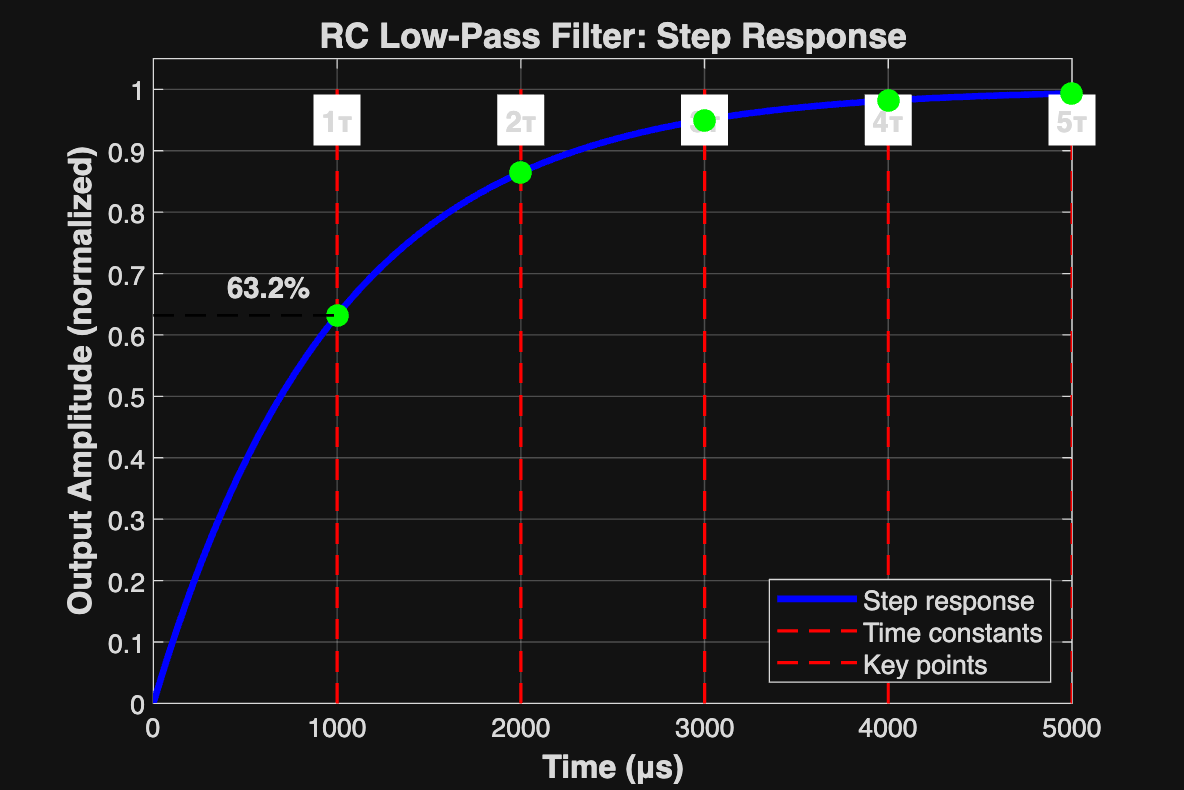

% Time vector for step response
t_step = linspace(0, 5*tau_rc, 1000);

% Compute step response
[y_step_rc, t_out_rc] = step(H_rc, t_step);

% Create step response plot
figure('Position', [100, 100, 900, 600]);
plot(t_out_rc*1e6, y_step_rc, 'b-', 'LineWidth', 2.5);
hold on;

% Mark time constants
for n = 1:5
    plot([n*tau_rc*1e6, n*tau_rc*1e6], [0, 1], 'r--', 'LineWidth', 1.2);
    text(n*tau_rc*1e6, 0.95, sprintf('%dτ', n), 'FontSize', 11, ...
         'HorizontalAlignment', 'center', 'BackgroundColor', 'white', 'FontWeight', 'bold');
end

% Mark key percentages
percentages = [0.632, 0.865, 0.950, 0.982, 0.993];
time_constants = [1, 2, 3, 4, 5];
for i = 1:length(percentages)
    plot(time_constants(i)*tau_rc*1e6, percentages(i), 'go', ...
         'MarkerSize', 8, 'MarkerFaceColor', 'g');
end

% Highlight 63.2% point
plot([0, tau_rc*1e6], [0.632, 0.632], 'k--', 'LineWidth', 1);
text(tau_rc*1e6*0.4, 0.68, '63.2%', 'FontSize', 11, 'FontWeight', 'bold');

hold off;
grid on;
xlabel('Time (μs)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Output Amplitude (normalized)', 'FontSize', 12, 'FontWeight', 'bold');
title('RC Low-Pass Filter: Step Response', 'FontSize', 13, 'FontWeight', 'bold');
legend('Step response', 'Time constants', 'Key points', 'Location', 'southeast', 'FontSize', 10);
xlim([0, 5*tau_rc*1e6]);
ylim([0, 1.05]);

## Time-Domain Characteristics

**Exponential Response Equation:**


$$V_{out}(t) = V_{in}(1 - e^{-t/\tau})$$


where τ = RC is the time constant.

**Key Time Response Points:**

- At t = τ: Output reaches 63.2% of final value

- At t = 2τ: Output reaches 86.5% of final value

- At t = 3τ: Output reaches 95.0% of final value

- At t = 4τ: Output reaches 98.2% of final value

- At t = 5τ: Output reaches 99.3% of final value (considered "settled")

**Physical Interpretation:**

The capacitor cannot charge instantaneously. The time constant τ determines how quickly the circuit responds. This smoothing effect removes high-frequency components (sharp edges) from input signals.

## 7. RL Low-Pass Filter

**Circuit Configuration**

An RL low-pass filter uses an inductor instead of a capacitor:

- A resistor (R) in series with the input

- An inductor (L) to ground

- Output voltage measured across the resistor

Circuit Topology:

Note: Output is across R (not L) to achieve low-pass response

**Transfer Function Derivation**

Impedances in s-domain:


$$Z_L = sL$$



$$Z_R = R$$


Using voltage divider:


$$H(s) = \frac{R}{R + sL} = \frac{R/L}{s + R/L}$$


Standard form:


$$H(s) = \frac{1}{1 + s\frac{L}{R}}$$


**Critical Frequency**

Occurs when inductive reactance equals resistance:


$$X_L = R$$



$$2\pi f_c L = R$$



$$f_c = \frac{R}{2\pi L}$$


**Time Constant**


$$\tau_{RL} = \frac{L}{R}$$


## 8. MATLAB Implementation - RL Low-Pass Filter

% RL Low-Pass Filter Parameters
R_rl = 1e3;              % Resistance = 1 kΩ
L_rl = 15.9e-3;          % Inductance = 15.9 mH (chosen for same fc as RC)

% Calculate critical frequency
fc_rl = R_rl / (2 * pi * L_rl);
tau_rl = L_rl / R_rl;

fprintf('RL LOW-PASS FILTER PARAMETERS:\n');

RL LOW-PASS FILTER PARAMETERS:


fprintf('================================\n');

fprintf('Resistance R = %.2f kΩ\n', R_rl/1e3);

Resistance R = 1.00 kΩ


fprintf('Inductance L = %.2f mH\n', L_rl/1e3);

Inductance L = 0.00 mH


fprintf('Critical frequency fc = %.2f Hz\n', fc_rl);

Critical frequency fc = 10009.74 Hz


fprintf('Time constant τ = %.2f μs\n', tau_rl/1e-6);

Time constant τ = 15.90 μs


fprintf('Roll-off rate: -20 dB/decade (single-pole)\n\n');

Roll-off rate: -20 dB/decade (single-pole)




% Create transfer function
H_rl = (R_rl/L_rl) / (s + R_rl/L_rl);

fprintf('RL Transfer Function H(s):\n');

RL Transfer Function H(s):


disp(H_rl);

  tf with properties:

       Numerator: {[0 6.2893e+04]}
     Denominator: {[1 6.2893e+04]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



## 9. Frequency Response - RL Filter

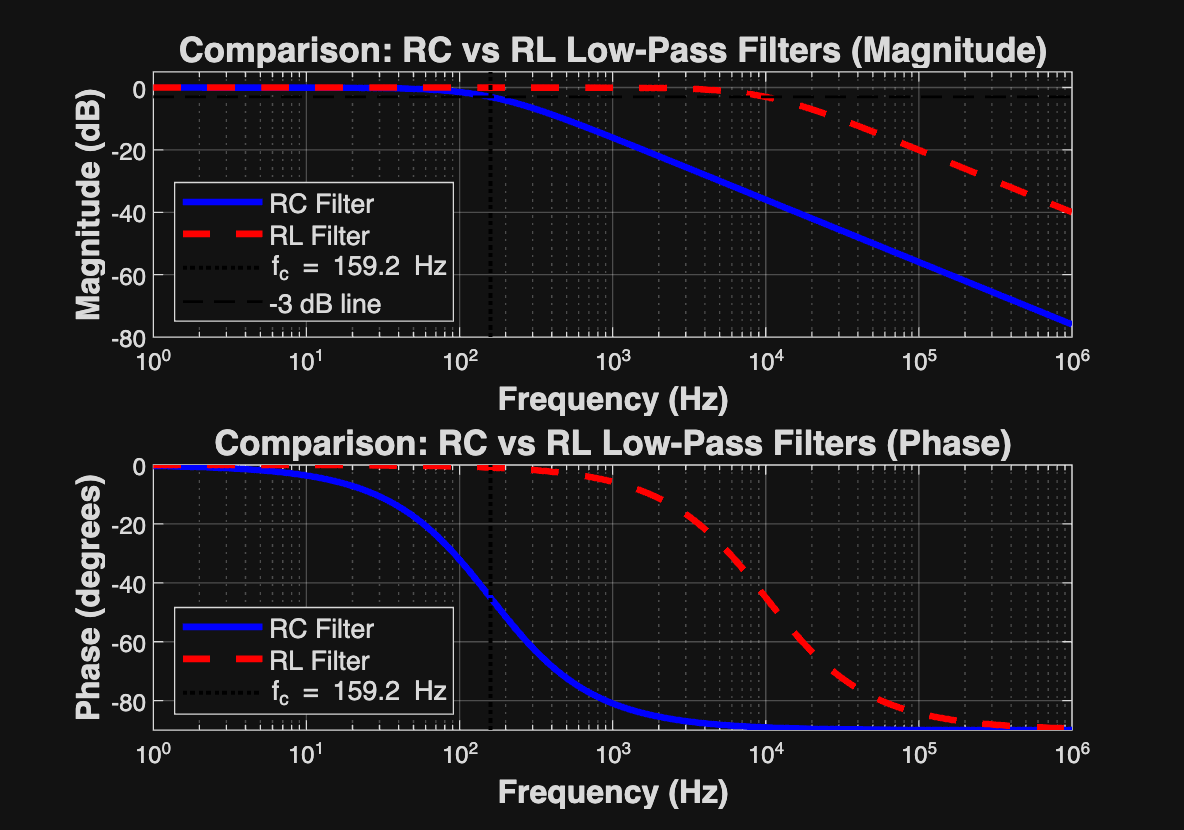

% Compute frequency response for RL filter
[mag_rl, phase_rl] = bode(H_rl, w);
mag_rl = squeeze(mag_rl);
phase_rl = squeeze(phase_rl);
mag_dB_rl = 20 * log10(mag_rl);

% Compare RC and RL filters
figure('Position', [100, 100, 1000, 700]);

% Magnitude comparison
subplot(2, 1, 1);
semilogx(f, mag_dB_rc, 'b-', 'LineWidth', 2.5);
hold on;
semilogx(f, mag_dB_rl, 'r--', 'LineWidth', 2.5);
semilogx([fc_rc, fc_rc], [-80, 5], 'k:', 'LineWidth', 1.5);
semilogx([f(1), f(end)], [-3, -3], 'k--', 'LineWidth', 1);
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');
title('Comparison: RC vs RL Low-Pass Filters (Magnitude)', 'FontSize', 13, 'FontWeight', 'bold');
legend('RC Filter', 'RL Filter', sprintf('f_c = %.1f Hz', fc_rc), ...
       '-3 dB line', 'Location', 'southwest', 'FontSize', 10);
ylim([-80, 5]);
xlim([f(1), f(end)]);

% Phase comparison
subplot(2, 1, 2);
semilogx(f, phase_rc, 'b-', 'LineWidth', 2.5);
hold on;
semilogx(f, phase_rl, 'r--', 'LineWidth', 2.5);
semilogx([fc_rc, fc_rc], [-90, 0], 'k:', 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Phase (degrees)', 'FontSize', 12, 'FontWeight', 'bold');
title('Comparison: RC vs RL Low-Pass Filters (Phase)', 'FontSize', 13, 'FontWeight', 'bold');
legend('RC Filter', 'RL Filter', sprintf('f_c = %.1f Hz', fc_rc), ...
       'Location', 'southwest', 'FontSize', 10);
ylim([-90, 0]);
xlim([f(1), f(end)]);

## RC vs RL Comparison

**Similarities:**

- Both are first-order (single-pole) filters

- Both have -20 dB/decade roll-off rate

- Both have -3 dB attenuation at critical frequency

- Both have -45° phase shift at critical frequency

**Differences:**

- RC filter: Uses capacitor (more common, cheaper, smaller)

- RL filter: Uses inductor (bulkier, more expensive, harder to integrate)

- RC formula: fc = 1/(2πRC)

- RL formula: fc = R/(2πL)

**Practical Consideration:**

RC filters are strongly preferred in modern electronics because inductors are bulky, expensive, and difficult to integrate into ICs. Active filters using op-amps with RC circuits avoid inductors entirely.

## 10. RLC Low-Pass Filter (Second-Order)

**Circuit Configuration**

An RLC low-pass filter combines all three passive elements:

Circuit Topology (Series RLC):

Output taken across the capacitor.

**Transfer Function**

The second-order RLC low-pass filter transfer function:


$$H(s) = \frac{\omega_0^2}{s^2 + 2\zeta\omega_0 s + \omega_0^2}$$


where:

- $\omega_0 = \frac{1}{\sqrt{LC}}$ is the natural frequency (rad/s)

- $\zeta = \frac{R}{2}\sqrt{\frac{C}{L}}$ is the damping ratio

**Critical Frequency**


$$f_0 = \frac{1}{2\pi\sqrt{LC}}$$


**Quality Factor**


$$Q = \frac{1}{2\zeta} = \frac{1}{R}\sqrt{\frac{L}{C}}$$


**Damping Ratio and Response Characteristics**

The damping ratio ζ determines the filter's response characteristic:

- ζ < 0.707: Underdamped (peaking in frequency response)

- ζ = 0.707: Critically damped (Butterworth response, maximally flat)

- ζ > 0.707: Overdamped (no peaking, slower roll-off initially)

## 11. MATLAB Implementation - RLC Low-Pass Filter

% Design RLC filter for same f0 as previous filters, Butterworth response
f0_rlc = fc_rc;          % Natural frequency = 1591.55 Hz
zeta = 1/sqrt(2);        % ζ = 0.707 for Butterworth (critically damped)

% Choose L, then calculate C and R for desired response
L_rlc = 10e-3;           % Inductance = 10 mH
C_rlc = 1 / ((2*pi*f0_rlc)^2 * L_rlc);
R_rlc = 2 * zeta * sqrt(L_rlc / C_rlc);

% Verify parameters
Q_rlc = 1 / (2*zeta);
omega0_rlc = 2 * pi * f0_rlc;

fprintf('RLC LOW-PASS FILTER PARAMETERS:\n');

RLC LOW-PASS FILTER PARAMETERS:


fprintf('=================================\n');

fprintf('Resistance R = %.2f Ω\n', R_rlc);

Resistance R = 14.14 Ω


fprintf('Inductance L = %.2f mH\n', L_rlc/1e-3);

Inductance L = 10.00 mH


fprintf('Capacitance C = %.2f nF\n', C_rlc/1e9);

Capacitance C = 0.00 nF


fprintf('Natural frequency f0 = %.2f Hz\n', f0_rlc);

Natural frequency f0 = 159.15 Hz


fprintf('Damping ratio ζ = %.3f (Butterworth)\n', zeta);

Damping ratio ζ = 0.707 (Butterworth)


fprintf('Quality factor Q = %.3f\n', Q_rlc);

Quality factor Q = 0.707


fprintf('Roll-off rate: -40 dB/decade (second-order)\n\n');

Roll-off rate: -40 dB/decade (second-order)




% Create transfer function
w0_rlc = 2 * pi * f0_rlc;
H_rlc = w0_rlc^2 / (s^2 + 2*zeta*w0_rlc*s + w0_rlc^2);

fprintf('RLC Transfer Function H(s):\n');

RLC Transfer Function H(s):


disp(H_rlc);

  tf with properties:

       Numerator: {[0 0 1000000]}
     Denominator: {[1 1.4142e+03 1000000]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



## 12. Frequency Response - RLC Filter

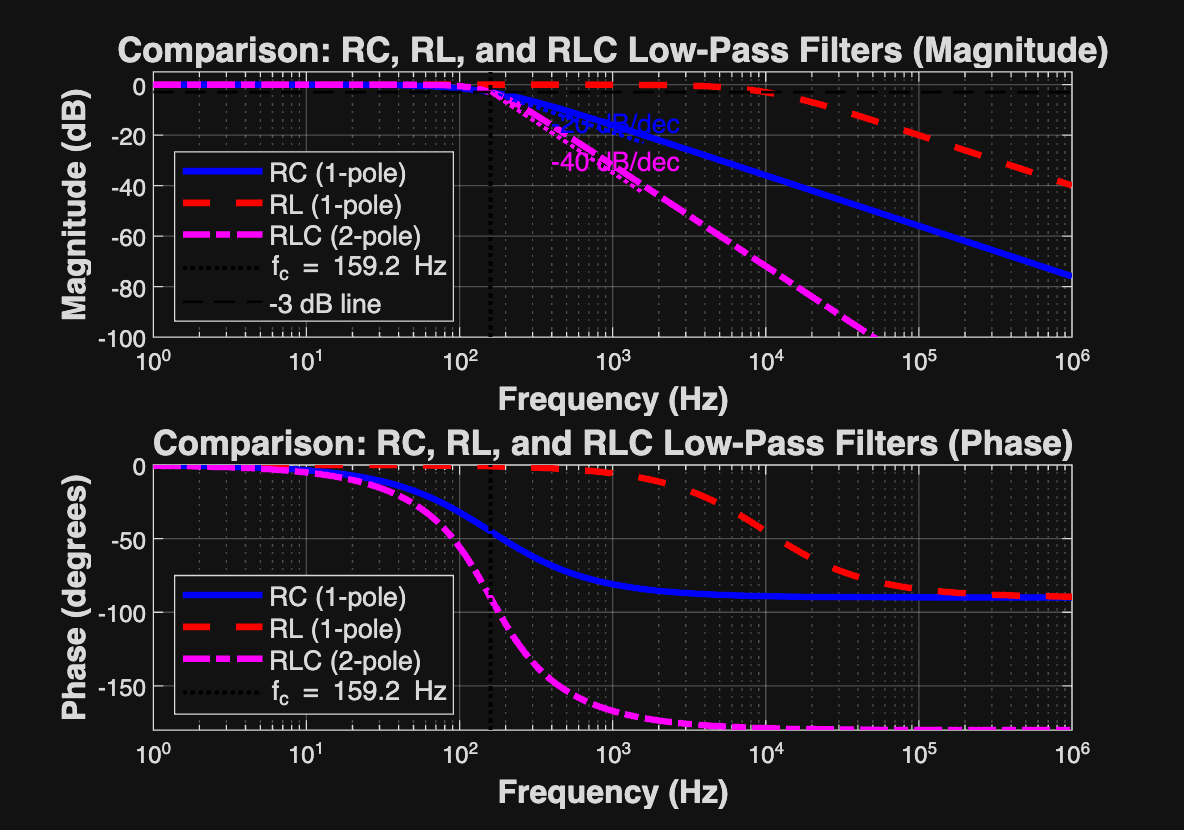

% Compute frequency response for RLC filter
[mag_rlc, phase_rlc] = bode(H_rlc, w);
mag_rlc = squeeze(mag_rlc);
phase_rlc = squeeze(phase_rlc);
mag_dB_rlc = 20 * log10(mag_rlc);

% Compare all three filters
figure('Position', [100, 100, 1000, 700]);

% Magnitude comparison
subplot(2, 1, 1);
semilogx(f, mag_dB_rc, 'b-', 'LineWidth', 2.5);
hold on;
semilogx(f, mag_dB_rl, 'r--', 'LineWidth', 2.5);
semilogx(f, mag_dB_rlc, 'm-.', 'LineWidth', 2.5);
semilogx([fc_rc, fc_rc], [-100, 5], 'k:', 'LineWidth', 1.5);
semilogx([f(1), f(end)], [-3, -3], 'k--', 'LineWidth', 1);

% Add roll-off annotations
f_decade = fc_rc * 10;
semilogx([fc_rc, f_decade], [-3, -23], 'b:', 'LineWidth', 1.5);
semilogx([fc_rc, f_decade], [-3, -43], 'm:', 'LineWidth', 1.5);
text(fc_rc*2.5, -15, '-20 dB/dec', 'FontSize', 10, 'Color', 'b');
text(fc_rc*2.5, -30, '-40 dB/dec', 'FontSize', 10, 'Color', 'm');

hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');
title('Comparison: RC, RL, and RLC Low-Pass Filters (Magnitude)', 'FontSize', 13, 'FontWeight', 'bold');
legend('RC (1-pole)', 'RL (1-pole)', 'RLC (2-pole)', sprintf('f_c = %.1f Hz', fc_rc), ...
       '-3 dB line', 'Location', 'southwest', 'FontSize', 10);
ylim([-100, 5]);
xlim([f(1), f(end)]);

% Phase comparison
subplot(2, 1, 2);
semilogx(f, phase_rc, 'b-', 'LineWidth', 2.5);
hold on;
semilogx(f, phase_rl, 'r--', 'LineWidth', 2.5);
semilogx(f, phase_rlc, 'm-.', 'LineWidth', 2.5);
semilogx([fc_rc, fc_rc], [-180, 0], 'k:', 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Phase (degrees)', 'FontSize', 12, 'FontWeight', 'bold');
title('Comparison: RC, RL, and RLC Low-Pass Filters (Phase)', 'FontSize', 13, 'FontWeight', 'bold');
legend('RC (1-pole)', 'RL (1-pole)', 'RLC (2-pole)', sprintf('f_c = %.1f Hz', fc_rc), ...
       'Location', 'southwest', 'FontSize', 10);
ylim([-180, 0]);
xlim([f(1), f(end)]);

## Analysis: Filter Order Effects

**Key Observations:**

- **First-order filters (RC, RL):** - Roll-off rate: -20 dB/decade - Phase shift: 0° to -90° - Simple, but gradual transition

- **Second-order filter (RLC):** - Roll-off rate: -40 dB/decade (twice as steep) - Phase shift: 0° to -180° - Sharper transition, better selectivity

- **Attenuation Comparison at 10×fc:** - First-order: -20 dB (10% of input) - Second-order: -40 dB (1% of input)

Higher-order filters provide better frequency selectivity but increase circuit complexity.

## 13. Filter Response Characteristics (Butterworth, Chebyshev, Bessel)

**Three Major Response Characteristics**

According to Floyd's textbook, each filter type can be designed with different response characteristics by adjusting the damping factor (DF):

- **Butterworth:** Maximally flat passband, no ripple, -20 dB/decade/pole

- **Chebyshev:** Ripple in passband, steeper roll-off than Butterworth

- **Bessel:** Linear phase response, best time-domain performance (no overshoot)

**Damping Factor (DF)**

The damping factor determines the response characteristic. For a second-order Butterworth response:


$$DF = 1.414 \quad (\zeta = 0.707)$$


Relationship between damping factor and damping ratio:


$$DF = 2\zeta$$


**Quality Factor (Q)**


$$Q = \frac{1}{DF}$$


For Butterworth: Q = 1/1.414 = 0.707

## 14. Implementing Different Response Characteristics

% Create RLC filters with different damping ratios

% Butterworth (ζ = 0.707, critically damped)
zeta_butter = 1/sqrt(2);
R_butter = 2 * zeta_butter * sqrt(L_rlc / C_rlc);
H_butter = w0_rlc^2 / (s^2 + 2*zeta_butter*w0_rlc*s + w0_rlc^2);

% Chebyshev-like (ζ = 0.5, underdamped - exhibits peaking)
zeta_cheby = 0.5;
R_cheby = 2 * zeta_cheby * sqrt(L_rlc / C_rlc);
H_cheby = w0_rlc^2 / (s^2 + 2*zeta_cheby*w0_rlc*s + w0_rlc^2);

% Bessel-like (ζ = 1.0, overdamped)
zeta_bessel = 1.0;
R_bessel = 2 * zeta_bessel * sqrt(L_rlc / C_rlc);
H_bessel = w0_rlc^2 / (s^2 + 2*zeta_bessel*w0_rlc*s + w0_rlc^2);

fprintf('RESPONSE CHARACTERISTICS COMPARISON:\n');

RESPONSE CHARACTERISTICS COMPARISON:


fprintf('=====================================\n');

fprintf('Butterworth: ζ = %.3f, R = %.2f Ω, Q = %.3f\n', zeta_butter, R_butter, 1/(2*zeta_butter));

Butterworth: ζ = 0.707, R = 14.14 Ω, Q = 0.707


fprintf('Chebyshev-like: ζ = %.3f, R = %.2f Ω, Q = %.3f\n', zeta_cheby, R_cheby, 1/(2*zeta_cheby));

Chebyshev-like: ζ = 0.500, R = 10.00 Ω, Q = 1.000


fprintf('Bessel-like: ζ = %.3f, R = %.2f Ω, Q = %.3f\n\n', zeta_bessel, R_bessel, 1/(2*zeta_bessel));

Bessel-like: ζ = 1.000, R = 20.00 Ω, Q = 0.500



## 15. Frequency Response - Different Characteristics

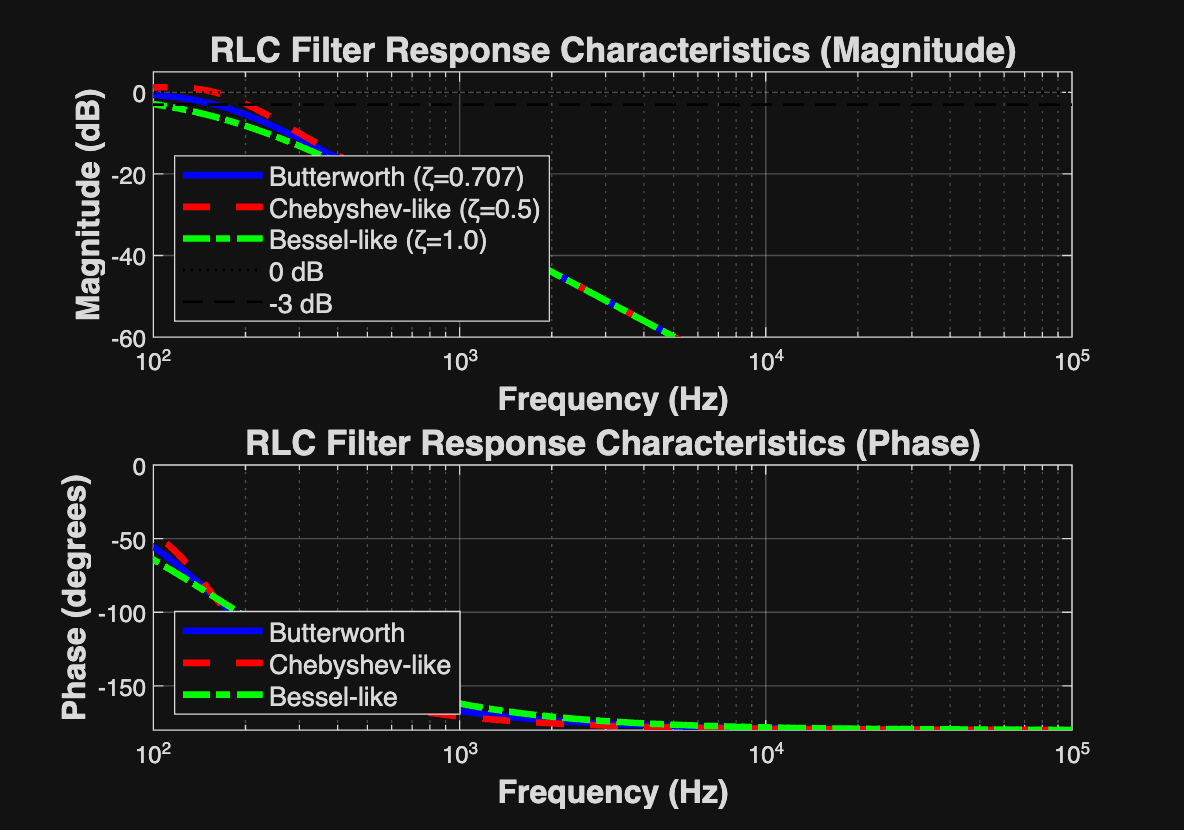

% Compute responses
[mag_butter, phase_butter] = bode(H_butter, w);
[mag_cheby, phase_cheby] = bode(H_cheby, w);
[mag_bessel, phase_bessel] = bode(H_bessel, w);

mag_butter = 20*log10(squeeze(mag_butter));
mag_cheby = 20*log10(squeeze(mag_cheby));
mag_bessel = 20*log10(squeeze(mag_bessel));

phase_butter = squeeze(phase_butter);
phase_cheby = squeeze(phase_cheby);
phase_bessel = squeeze(phase_bessel);

% Plot comparison
figure('Position', [100,100, 1000, 700]);
% Magnitude
subplot(2, 1, 1);
semilogx(f, mag_butter, 'b-', 'LineWidth', 2.5);
hold on;
semilogx(f, mag_cheby, 'r--', 'LineWidth', 2.5);
semilogx(f, mag_bessel, 'g-.', 'LineWidth', 2.5);
semilogx([f(1), f(end)], [0, 0], 'k:', 'LineWidth', 1);
semilogx([f(1), f(end)], [-3, -3], 'k--', 'LineWidth', 1);
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');
title('RLC Filter Response Characteristics (Magnitude)', 'FontSize', 13, 'FontWeight', 'bold');
legend('Butterworth (ζ=0.707)', 'Chebyshev-like (ζ=0.5)', 'Bessel-like (ζ=1.0)', ...
'0 dB', '-3 dB', 'Location', 'southwest', 'FontSize', 10);
ylim([-60, 5]);
xlim([100, 1e5]);
% Phase
subplot(2, 1, 2);
semilogx(f, phase_butter, 'b-', 'LineWidth', 2.5);
hold on;
semilogx(f, phase_cheby, 'r--', 'LineWidth', 2.5);
semilogx(f, phase_bessel, 'g-.', 'LineWidth', 2.5);
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Phase (degrees)', 'FontSize', 12, 'FontWeight', 'bold');
title('RLC Filter Response Characteristics (Phase)', 'FontSize', 13, 'FontWeight', 'bold');
legend('Butterworth', 'Chebyshev-like', 'Bessel-like', 'Location', 'southwest', 'FontSize', 10);
ylim([-180, 0]);
xlim([100, 1e5]);

## Analysis of Response Characteristics

Butterworth Response (Maximally Flat):

- Flat passband response (no ripple)

- Moderate roll-off rate: -40 dB/decade for 2-pole

- No peaking at cutoff frequency

- Good all-around performance

- Most widely used characteristic

Chebyshev-like Response (Steeper Roll-off):

- Exhibits peaking/ripple in passband (underdamped, ζ < 0.707)

- Steeper initial roll-off compared to Butterworth

- Higher Q factor (Q = 1.0 for ζ = 0.5)

- Used when sharp cutoff is critical

- Poorer time-domain response (overshoot)

Bessel-like Response (Linear Phase):

- Most linear phase response

- Gentler initial roll-off (overdamped, ζ > 0.707)

- Best time-domain characteristics (minimal overshoot)

- Preferred for pulse and digital signal filtering

- Lower Q factor

## 16. Time-Domain Comparison - Response Characteristics

Step response for each characteristic

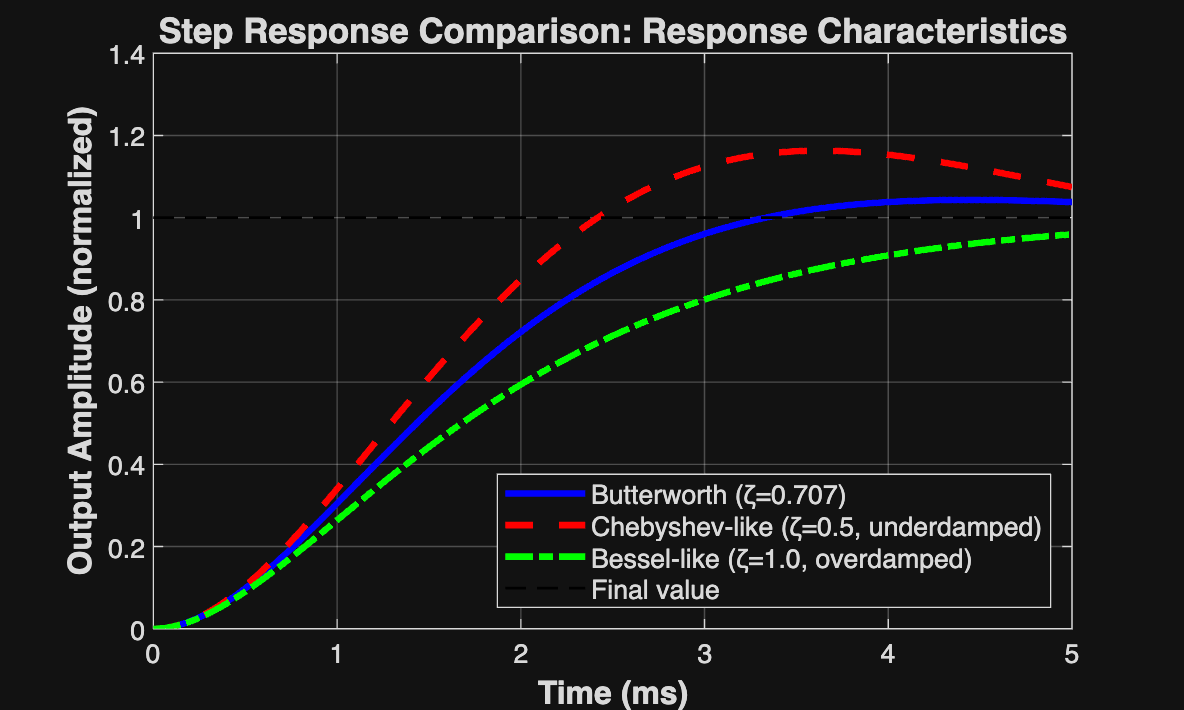

t_compare = linspace(0, 5e-3, 2000);
[y_butter, t_butter] = step(H_butter, t_compare);
[y_cheby, t_cheby] = step(H_cheby, t_compare);
[y_bessel, t_bessel] = step(H_bessel, t_compare);
figure('Position', [100, 100, 1000, 600]);
plot(t_butter*1e3, y_butter, 'b-', 'LineWidth', 2.5);
hold on;
plot(t_cheby*1e3, y_cheby, 'r--', 'LineWidth', 2.5);
plot(t_bessel*1e3, y_bessel, 'g-.', 'LineWidth', 2.5);
plot([0, max(t_compare)*1e3], [1, 1], 'k--', 'LineWidth', 1);
hold off;
grid on;
xlabel('Time (ms)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Output Amplitude (normalized)', 'FontSize', 12, 'FontWeight', 'bold');
title('Step Response Comparison: Response Characteristics', 'FontSize', 13, 'FontWeight', 'bold');
legend('Butterworth (ζ=0.707)', 'Chebyshev-like (ζ=0.5, underdamped)', ...
'Bessel-like (ζ=1.0, overdamped)', 'Final value', ...
'Location', 'southeast', 'FontSize', 10);
ylim([0, 1.4]);
xlim([0, 5]);

## Time-Domain Analysis

Observations from Step Response:

- Butterworth: Moderate overshoot (~4%), good compromise

- Chebyshev-like (underdamped): Significant overshoot and ringing, fastest initial rise

- Bessel-like (overdamped): No overshoot, slowest response, best for preserving waveform shape

Application Guidelines:

- Use Butterworth for general-purpose filtering (balanced performance)

- Use Chebyshev when sharp frequency cutoff is essential and overshoot is acceptable

- Use Bessel when maintaining pulse shape and minimizing distortion is critical

## 17. Cascading Filters for Higher Orders

Multi-Order Filter Implementation

From Floyd's textbook: To obtain filters with three or more poles, one-pole or two-pole filters are cascaded. Each filter stage is called a section.

Cascading Rules:

- Third-order: Cascade 2-pole + 1-pole filter

- Fourth-order: Cascade two 2-pole filters

- Fifth-order: Cascade 2-pole + 2-pole + 1-pole

- Sixth-order: Cascade three 2-pole filters

Roll-off Rates:

- 1st order: -20 dB/decade

- 2nd order: -40 dB/decade

- 3rd order: -60 dB/decade

- 4th order: -80 dB/decade

- nth order: -20n dB/decade

## 18. Example: Cascaded Filters (3rd and 4th Order)

Create cascaded filter systems Third-order: Cascade two RC stages (first-order) + one RLC stage (second-order)

H_rc_stage = 1 / (1 + s*R_rc*C_rc);
H_3rd_order = H_rc_stage * H_butter;  % 1-pole + 2-pole = 3-pole
% Fourth-order: Cascade two RLC Butterworth stages (two second-order)
H_4th_order = H_butter * H_butter;    % 2-pole + 2-pole = 4-pole
fprintf('CASCADED FILTER CONFIGURATIONS:\n');

CASCADED FILTER CONFIGURATIONS:


fprintf('================================\n');

fprintf('3rd-order (3-pole): Roll-off = -60 dB/decade\n');

3rd-order (3-pole): Roll-off = -60 dB/decade


fprintf('4th-order (4-pole): Roll-off = -80 dB/decade\n\n');

4th-order (4-pole): Roll-off = -80 dB/decade



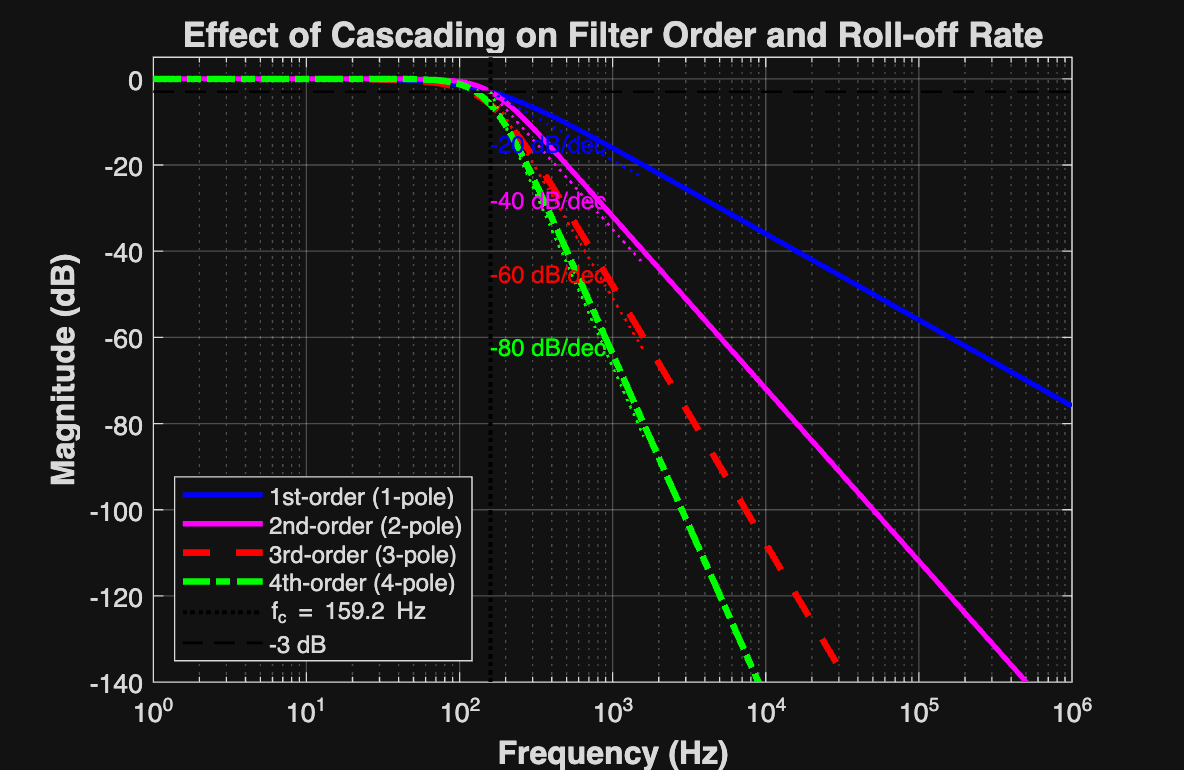

% Compute responses
[mag_3rd, ~] = bode(H_3rd_order, w);
[mag_4th, ~] = bode(H_4th_order, w);
mag_3rd = 20*log10(squeeze(mag_3rd));
mag_4th = 20*log10(squeeze(mag_4th));
% Plot cascaded responses with original filters
figure('Position', [100, 100, 1000, 650]);
semilogx(f, mag_dB_rc, 'b-', 'LineWidth', 2);
hold on;
semilogx(f, mag_dB_rlc, 'm-', 'LineWidth', 2);
semilogx(f, mag_3rd, 'r--', 'LineWidth', 2.5);
semilogx(f, mag_4th, 'g-.', 'LineWidth', 2.5);
semilogx([fc_rc, fc_rc], [-140, 5], 'k:', 'LineWidth', 1.5);
semilogx([f(1), f(end)], [-3, -3], 'k--', 'LineWidth', 1);
% Add roll-off rate lines
f_decade = fc_rc * 10;
semilogx([fc_rc, f_decade], [-3, -23], 'b:', 'LineWidth', 1);
semilogx([fc_rc, f_decade], [-3, -43], 'm:', 'LineWidth', 1);
semilogx([fc_rc, f_decade], [-3, -63], 'r:', 'LineWidth', 1);
semilogx([fc_rc, f_decade], [-3, -83], 'g:', 'LineWidth', 1);
text(fc_rc, -15, '-20 dB/dec', 'FontSize', 9, 'Color', 'b');
text(fc_rc, -28, '-40 dB/dec', 'FontSize', 9, 'Color', 'm');
text(fc_rc, -45, '-60 dB/dec', 'FontSize', 9, 'Color', 'r');
text(fc_rc, -62, '-80 dB/dec', 'FontSize', 9, 'Color', 'g');
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');
title('Effect of Cascading on Filter Order and Roll-off Rate', 'FontSize', 13, 'FontWeight', 'bold');
legend('1st-order (1-pole)', '2nd-order (2-pole)', '3rd-order (3-pole)', ...
'4th-order (4-pole)', sprintf('f_c = %.1f Hz', fc_rc), '-3 dB', ...
'Location', 'southwest', 'FontSize', 9);
ylim([-140, 5]);
xlim([f(1), f(end)]);

## Cascading Analysis

Effect of Increasing Filter Order:

- Each additional pole adds -20 dB/decade to roll-off rate

- Transition region becomes increasingly steep

- Better frequency selectivity with higher orders

- More complex circuitry required

Practical Trade-offs:

- Higher order → Better selectivity

- Higher order → Increased component count

- Higher order → Greater phase shift

- Higher order → More sensitivity to component tolerances

Butterworth Table (from Floyd, Table 15-1):

## 19. Summary Table: Filter Configurations

Create comprehensive summary

fprintf('\n');
fprintf('========================================================================\n');

fprintf('                   PASSIVE LOW-PASS FILTER SUMMARY\n');

                   PASSIVE LOW-PASS FILTER SUMMARY


fprintf('========================================================================\n\n');

fprintf('FILTER TYPE         POLES   ROLL-OFF        CRITICAL FREQUENCY\n');

FILTER TYPE         POLES   ROLL-OFF        CRITICAL FREQUENCY


fprintf('------------------------------------------------------------------------\n');

------------------------------------------------------------------------


fprintf('RC Filter           1       -20 dB/dec      fc = 1/(2πRC)\n');

RC Filter           1       -20 dB/dec      fc = 1/(2πRC)


fprintf('RL Filter           1       -20 dB/dec      fc = R/(2πL)\n');

RL Filter           1       -20 dB/dec      fc = R/(2πL)


fprintf('RLC Filter          2       -40 dB/dec      f0 = 1/(2π√LC)\n');

RLC Filter          2       -40 dB/dec      f0 = 1/(2π√LC)


fprintf('3rd-order Cascade   3       -60 dB/dec      Determined by stages\n');

3rd-order Cascade   3       -60 dB/dec      Determined by stages


fprintf('4th-order Cascade   4       -80 dB/dec      Determined by stages\n');

4th-order Cascade   4       -80 dB/dec      Determined by stages


fprintf('------------------------------------------------------------------------\n\n');

------------------------------------------------------------------------



fprintf('RESPONSE CHARACTERISTICS:\n');

RESPONSE CHARACTERISTICS:


fprintf('------------------------------------------------------------------------\n');

------------------------------------------------------------------------


fprintf('Butterworth:  Maximally flat, ζ=0.707, Q=0.707, no ripple\n');

Butterworth:  Maximally flat, ζ=0.707, Q=0.707, no ripple


fprintf('Chebyshev:    Ripple in passband, steeper roll-off, ζ<0.707, Q>1\n');

Chebyshev:    Ripple in passband, steeper roll-off, ζ<0.707, Q>1


fprintf('Bessel:       Linear phase, minimal overshoot, ζ>0.707, Q<0.707\n');

Bessel:       Linear phase, minimal overshoot, ζ>0.707, Q<0.707


fprintf('------------------------------------------------------------------------\n\n');

------------------------------------------------------------------------



fprintf('KEY RELATIONSHIPS:\n');

KEY RELATIONSHIPS:


fprintf('------------------------------------------------------------------------\n');

------------------------------------------------------------------------


fprintf('Quality Factor:       Q = 1/DF = 1/(2ζ)\n');

Quality Factor:       Q = 1/DF = 1/(2ζ)


fprintf('Damping Factor:       DF = 2ζ\n');

Damping Factor:       DF = 2ζ


fprintf('For Butterworth:      ζ = 1/√2 ≈ 0.707, DF = √2 ≈ 1.414\n');

For Butterworth:      ζ = 1/√2 ≈ 0.707, DF = √2 ≈ 1.414


fprintf('Roll-off per pole:    -20 dB/decade = -6 dB/octave\n');

Roll-off per pole:    -20 dB/decade = -6 dB/octave


fprintf('Critical frequency:   Output = 0.707 × Input = -3 dB\n');

Critical frequency:   Output = 0.707 × Input = -3 dB


fprintf('------------------------------------------------------------------------\n');

------------------------------------------------------------------------


## 20. Practical Design Considerations

Component Selection Guidelines:

- RC Filters: - Most common in modern electronics - Use 1% resistors for precision - Use film capacitors (not electrolytics) for AC signals - Keep RC product between 1 μs and 1 ms typically

- RL Filters: - Avoid if possible (inductors are bulky and expensive) - Useful in power applications - Consider DC resistance of inductor - Watch for magnetic coupling with nearby circuits

- RLC Filters: - Provide sharper cutoff than single-pole filters - Require careful component selection to achieve desired Q - Component tolerances significantly affect response - Consider using active filters instead for better control

Active vs. Passive Filters:

According to Floyd's textbook:

- Active filters use op-amps with RC circuits (no inductors)

- Advantages: Gain, no loading effects, easier to adjust

- Active filters can achieve steep roll-off rates without inductors

- Passive filters: Simple, no power supply needed, but suffer from loading

When to Use Passive Filters:

- Simple applications with relaxed specifications

- No power supply available

- Very high frequency applications (beyond op-amp bandwidth)

- Power supply filtering

- Cost-sensitive designs

## 21. Filter Performance Metrics Summary

Calculate key performance metrics for comparison

filters_data = struct();
% RC Filter metrics
filters_data(1).name = 'RC (1-pole)';
filters_data(1).fc = fc_rc;
filters_data(1).rolloff = -20;
filters_data(1).phase_at_fc = -45;
filters_data(1).atten_10fc = -20;
% RLC Butterworth metrics
filters_data(2).name = 'RLC Butterworth (2-pole)';
filters_data(2).fc = f0_rlc;
filters_data(2).rolloff = -40;
filters_data(2).phase_at_fc = -90;
filters_data(2).atten_10fc = -40;
% 3rd order metrics
filters_data(3).name = '3rd-order Cascade';
filters_data(3).fc = fc_rc;
filters_data(3).rolloff = -60;
filters_data(3).phase_at_fc = -135;
filters_data(3).atten_10fc = -60;
% 4th order metrics
filters_data(4).name = '4th-order Cascade';
filters_data(4).fc = fc_rc;
filters_data(4).rolloff = -80;
filters_data(4).phase_at_fc = -180;
filters_data(4).atten_10fc = -80;
% Display comparison table
fprintf('\n');
fprintf('PERFORMANCE COMPARISON AT fc = %.1f Hz:\n', fc_rc);

PERFORMANCE COMPARISON AT fc = 159.2 Hz:


fprintf('========================================================================\n');

fprintf('Filter Type              Roll-off    Phase@fc   Atten@10fc  Order\n');

Filter Type              Roll-off    Phase@fc   Atten@10fc  Order


fprintf('------------------------------------------------------------------------\n');

------------------------------------------------------------------------


for i = 1:length(filters_data)
fprintf('%-23s  %3d dB/dec   %4d°      %3d dB      %d\n', ...
filters_data(i).name, filters_data(i).rolloff, ...
filters_data(i).phase_at_fc, filters_data(i).atten_10fc, i);
end

RC (1-pole)              -20 dB/dec    -45°      -20 dB      1
RLC Butterworth (2-pole)  -40 dB/dec    -90°      -40 dB      2
3rd-order Cascade        -60 dB/dec   -135°      -60 dB      3
4th-order Cascade        -80 dB/dec   -180°      -80 dB      4


fprintf('========================================================================\n\n');

## 22. Design Example: Audio Noise Filter

Practical Design Scenario

Design a low-pass filter to remove noise above 20 kHz from an audio signal (human hearing range: 20 Hz to 20 kHz).

Requirements:

- Cutoff frequency: fc = 20 kHz

- Minimum attenuation at 40 kHz: -20 dB

- Flat passband response (Butterworth)

- Minimal component count Design specifications

fc_audio = 20e3;        % 20 kHz cutoff
f_test = 40e3;          % Test frequency (2×fc)
atten_required = -20;   % Required attenuation in dB
% Determine required order
% At 2×fc: 1 decade = 10×fc, so 2×fc is 0.301 decade above fc
decades_to_test = log10(f_test / fc_audio);
% For n-pole filter: attenuation = -20n × decades
% Solve: -20n × decades ≥ atten_required
n_required = ceil(abs(atten_required) / (20 * decades_to_test));
fprintf('AUDIO FILTER DESIGN EXAMPLE:\n');

AUDIO FILTER DESIGN EXAMPLE:


fprintf('=============================\n');

fprintf('Cutoff frequency: %.1f kHz\n', fc_audio/1e3);

Cutoff frequency: 20.0 kHz


fprintf('Test frequency: %.1f kHz (%.2f decades above fc)\n', f_test/1e3, decades_to_test);

Test frequency: 40.0 kHz (0.30 decades above fc)


fprintf('Required attenuation at test frequency: %.1f dB\n', atten_required);

Required attenuation at test frequency: -20.0 dB


fprintf('Required filter order: %d poles\n', n_required);

Required filter order: 4 poles


fprintf('Selected configuration: RC (single-pole) filter\n\n');

Selected configuration: RC (single-pole) filter



% Design RC filter
C_audio = 1e-9;  % Choose 1 nF (standard value)
R_audio = 1 / (2 * pi * fc_audio * C_audio);
% Find nearest standard resistor value (E24 series)
E24_values = [10, 11, 12, 13, 15, 16, 18, 20, 22, 24, 27, 30, 33, 36, 39, ...
43, 47, 51, 56, 62, 68, 75, 82, 91];
decades = floor(log10(R_audio));
normalized = R_audio / (10^decades);
[~, idx] = min(abs(E24_values - normalized*10));
R_audio_std = E24_values(idx) * 10^(decades-1);
% Recalculate actual cutoff with standard value
fc_audio_actual = 1 / (2 * pi * R_audio_std * C_audio);
fprintf('Component Selection:\n');

Component Selection:


fprintf('Calculated R = %.2f Ω\n', R_audio);

Calculated R = 7957.75 Ω


fprintf('Standard R = %.0f Ω (E24 series)\n', R_audio_std);

Standard R = 8200 Ω (E24 series)


fprintf('Selected C = %.0f nF\n', C_audio/1e-9);

Selected C = 1 nF


fprintf('Actual cutoff frequency = %.2f kHz\n', fc_audio_actual/1e3);

Actual cutoff frequency = 19.41 kHz


fprintf('Frequency error = %.2f%%\n', (fc_audio_actual - fc_audio)/fc_audio * 100);

Frequency error = -2.95%


% Create and analyze audio filter
H_audio = 1 / (1 + s*R_audio_std*C_audio);
% Verify attenuation at test frequency
[mag_at_40k, ~] = bode(H_audio, 2*pi*f_test);
atten_at_40k = 20*log10(mag_at_40k);
fprintf('\nPerformance Verification:\n');


Performance Verification:


fprintf('Attenuation at %.1f kHz = %.2f dB\n', f_test/1e3, atten_at_40k);

Attenuation at 40.0 kHz = -7.20 dB


if atten_at_40k <= atten_required
fprintf('✓ Design meets specification (≤ %.1f dB)\n', atten_required);
else
fprintf('✗ Design does NOT meet specification\n');
fprintf('  Consider using a 2nd-order filter for %.1f dB at %.1f kHz\n', ...
atten_required, f_test/1e3);
end

✗ Design does NOT meet specification


  Consider using a 2nd-order filter for -20.0 dB at 40.0 kHz


## 23. Conclusion and Key Takeaways

Summary of Passive Low-Pass Filters:

- RC Filters: Most common, simple, use formula fc = 1/(2πRC)

- RL Filters: Less common, avoid inductors when possible, fc = R/(2πL)

- RLC Filters: Second-order, sharper cutoff, f0 = 1/(2π√LC)

- Roll-off Rate: -20 dB/decade per pole (order)

- Critical Frequency: Where output drops to 70.7% (-3 dB) of passband value

Response Characteristics (Butterworth, Chebyshev, Bessel):

- Determined by damping ratio (ζ) or damping factor (DF = 2ζ)

- Butterworth (ζ = 0.707): Maximally flat, most widely used

- Chebyshev (ζ < 0.707): Ripple, steeper roll-off

- Bessel (ζ > 0.707): Linear phase, best time response

Cascading Filters:

- Increases order and roll-off rate

- 3rd-order: 2-pole + 1-pole = -60 dB/decade

- 4th-order: 2-pole + 2-pole = -80 dB/decade

- Each pole contributes -20 dB/decade

Practical Considerations:

- Use RC filters when possible (avoid inductors)

- Consider active filters for better performance and control

- Account for component tolerances in design

- Match filter order to selectivity requirements

MATLAB Analysis Tools Used:

- Transfer function modeling with tf() and symbolic s

- Bode plots with bode() function

- Step response with step() function

- Frequency domain analysis with logarithmic scaling

Further Topics for Study:

- Active low-pass filters using op-amps (Chapter 15-3 in Floyd)

- Sallen-Key filter topology

- Multiple feedback filter configurations

- Digital filter equivalents (IIR filters)

- Filter design tables and normalized values

End of Tutorial

## References

Primary Source:

Floyd, T. L. (2018). Electronic Devices (10th Global Edition). Pearson Education Limited. Chapter 15: Active Filters.

Key Concepts Covered:

- Section 15-1: Basic Filter Responses

- Section 15-2: Filter Response Characteristics

- Section 15-3: Active Low-Pass Filters (Introduction)

Additional Resources:

- MATLAB Control System Toolbox Documentation

- Filter design handbooks

- Application notes on analog filter design